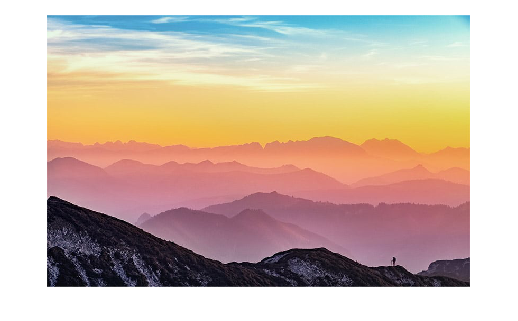

% img = imread('project\images\MVP-4_Rityta_1.png')
% img = im2double(img)

t = Tiff('project\images\lighting.tif','r');
% t = Tiff('project\images\MVP_2.tif','r');
img = read(t);
img = im2double(img);

imshow(img);

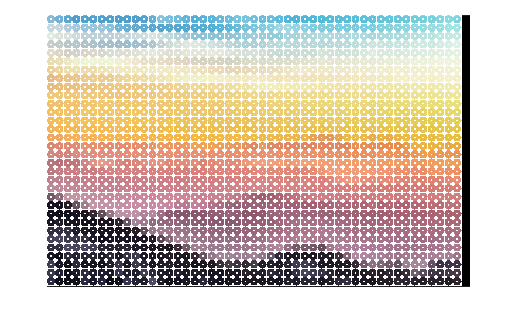


board = pearlBoard(img, 16);
imshow(board)

function result = pearlBoard(image, pearlSize)
    % Input: An image and the size of the pearl (in width)
    % Output: A copy of the image but displayed using pearls

    [x, y, z] = size(image);
    board = zeros(x,y,z,'double');

    for r = 1:pearlSize:x-pearlSize
        for c = 1:pearlSize:y-pearlSize
            part = image(r:r+pearlSize-1,c:c+pearlSize-1, :);
            % förändring av part
            pearl = makePearl(part);
            board(r:r+pearlSize-1,c:c+pearlSize-1, :) = pearl;
        end
    end

    result = board;
end

function part = makePearl(part)
    % Input: A part of an image which will be converted to a pearl
    % Output: An image the same size as the part but converted to a pearl

    [x, y, ~] = size(part);
    middle = x/2;
    color = getMeanColor(part);
    for r = 1:x
        for c = 1:y
            d = sqrt((r-middle)^2 + (c-middle)^2);
            if d > uint8(x*0.5)
                part(r,c, :) = 1;
            elseif d <  uint8(x*0.1)
                part(r,c, :) = 1;
            else
                part(r,c, :) = color;
            end
        end
    end
end

function color = getMeanColor(part)
    % Input: A part of an image representing a pearl
    % Output: A 1 by 3 vector containing the mean color in the part
    
    redChannel = part(:,:,1);
    greenChannel = part(:,:,2);
    blueChannel = part(:,:,3);
    
    meanR = mean((mean(redChannel)));
    meanG = mean(mean(greenChannel));
    meanB = mean(mean(blueChannel));

    color = [meanR, meanG, meanB];
end